data = readtable('data_active_pos_fb.xml');

### Plot all wheel speed data

Note ' transposes a matrix

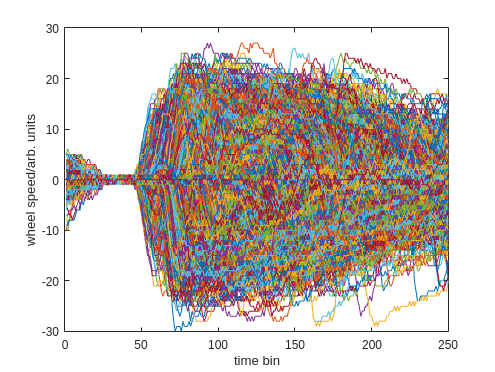

clf
plot(data.wheel_speed')

xlabel('time bin')
ylabel('wheel speed/arb. units')

### Plot wheel speed for mouse with interactive selection

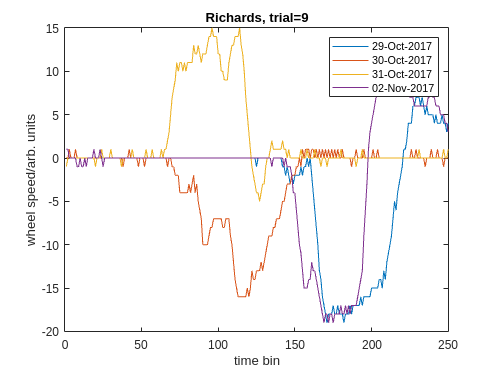

mouse_names = unique(data.mouse);

mn = mouse_names(8);

idx= (data.mouse==mn & data.trial==9 );
selected_data = data(idx,:);

dates= datestr(selected_data .session_date);
plot(selected_data.wheel_speed')

title(sprintf('%s, trial=%d', mn,unique(selected_data.trial)))
xlabel('time bin')
ylabel('wheel speed/arb. units')
legend(dates)

### Subplots

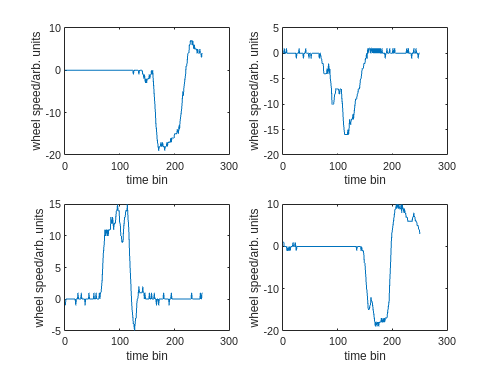

ss = size(selected_data);

for i=1 : ss(1)
    ax= subplot(2,2,i);
    plot(selected_data{i, "wheel_speed"}, 'DisplayName',datestr(selected_data{i, "session_date"}))
    xlabel('time bin')
    ylabel('wheel speed/arb. units')
end

clf
